# Compressing historical weather data

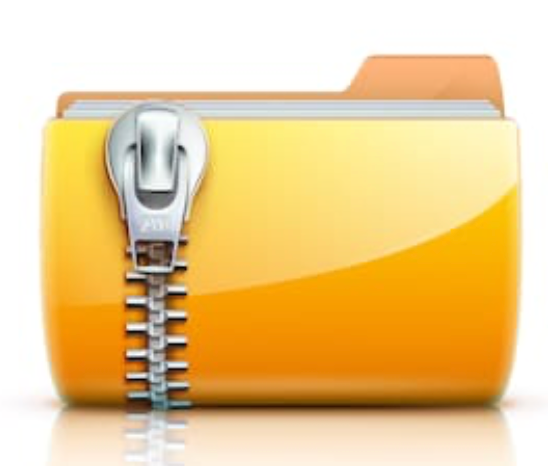

Note: Press the button 'Run section' in the live editor tab to sequencially run the code provided below at each section.

## **Introduction**

One application of the Discrete Fourier Transform is data compression. For instance the famous JPEG image format relies on a straightforward variant of the Discrete Fourier Transform, called the Discrete Cosine Transform, see [https://en.wikipedia.org/wiki/JPEG.](https://en.wikipedia.org/wiki/JPEG.) Differently from lossless compression methods, used for instance in the ZIP file format, methods that rely on the Discrete Fourier Transform are typically lossy, but can achieve much higher size reductions. 

In this live script we use the Discrete Fourier Transform to reduce the size of a file larger than 100MB containing historical weather data in Eindhoven from 00h00 January 1st, 1979 until December 23h59, 31st, 2019. You might be analysing similar temperature data of more than 1000 cities and simply do not have enough storage space to store this data.

Let us start by getting the data using the following instruction, which imports it from a remote location into variable `weatherEindhoven `in your workspace

load weatherEindhoven.mat

The data captures the temperature at each minute in the mentioned time period. The number of minutes from 00h00 January 1st, 1979 until 23h59, December 31st, 2019 is $41 \times 365 \times 24 \times 60 + 10\times 24\times 60=21564000$, which is indeed the size $N$ of the `weatherEindhoven, `so that `weatherEindhoven(i) `is the temperature in the $i$th minute after 00h00 January 1st, 1979. The temperature at each hour was obtained from [https://openweathermap.org/history-bulk](https://openweathermap.org/history-bulk). Since the data at each minute is not available an interpolation technique was used to simulate small fluctuations in every hour, which is not detailed here. The following instruction plots the temperature from 00h00 December 22nd, 2019 until 23h59, December 31st, 2019.

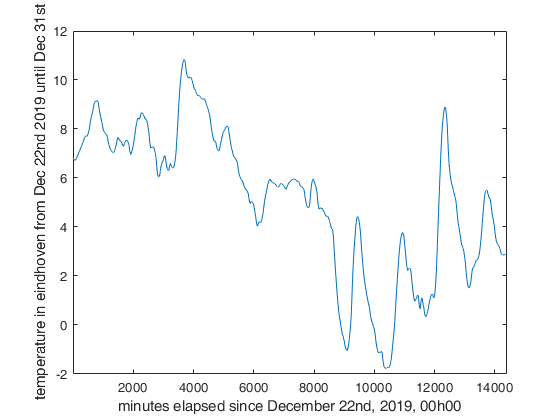

figure(1)
plot([1:10*24*60],weatherEindhoven(end-10*24*60+1:end))
axis([1 10*24*60 -2 12])
xlabel('minutes elapsed since December 22nd, 2019, 00h00'), ylabel('temperature in eindhoven from Dec 22nd 2019 until Dec 31st')

## **Intermezzo **

But first things first. Since the global warming is much more important than the signals and systems course we start by checking that indeed the temperature is worryingly increasing, by ploting the anual average temperature in the 41 years of the considered period from 1979 until 2019.

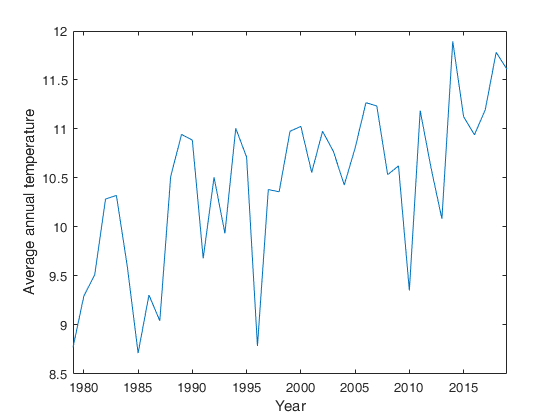

ind = 1;
for j = 1:41
    if mod(1979+j-1,4) == 0
        avweatherEindhoven(j) = mean(weatherEindhoven(ind:60:ind*24:ind+366*24*60-1));
        ind = ind+366*24*60;
    else
        avweatherEindhoven(j) = mean(weatherEindhoven(ind:60:ind+365*24*60-1));
        ind = ind+365*24*60;
    end
end

figure(2)
plot(1979:1:2019,avweatherEindhoven)
axis([1979 2019 8.5 12]), xlabel('Year'), ylabel('Average annual temperature')

Please do something about this!

## **General thoughts on compressing data**

Let us now go back to the signals and systems course. We want to compress the vector `weatherEindhoven `which contains $N=21564000$ real numbers. Lossless compression methods such as zipping the file will not get us very far. For instance if you save the data

`save myLocalData weatherEindhoven`

you will get a file with 135.9 MB. Trying to zip with the Mac OS instruction 'compress' it we get approximately the same size (try with your own compressor).

On the other hand, we could of course simply subsample this signal and have, say, just the temperature once per day, say at 12h00 (noon).  This would reduce the amount of data by a factor $24 \times 60$, leading to a vector with $\frac{21564000}{24 
\times 60}=14975$  components which requires less than 1MB to store. However, a lot of information would be lost, e.g., we would loose the information on how the temperature changes during the day. Perhaps the nights are getting relatively warmer with the global warming than during daytime and this information would be lost. For future reference the following instructions will give us a signal which approximates at every minute of each day the temperature by the temperature of that day at 12h00.

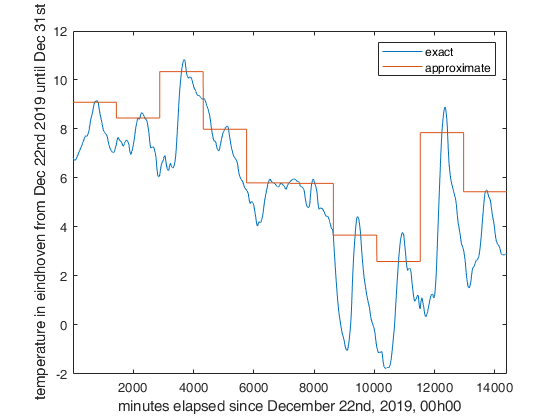

ind = 1;
approxweatherEindhoven = zeros(1,length(weatherEindhoven));
for j = 1:365*41+10 % # of days is (365*41+10)
    approxweatherEindhoven(1,ind:1:ind+24*60-1) = ones(1,24*60)*weatherEindhoven(ind+60*12);
    ind = ind+24*60;
end

figure(3)
plot([1:10*24*60],weatherEindhoven(end-10*24*60+1:end)), hold on % plot for last 10 days
plot([1:10*24*60],approxweatherEindhoven(end-10*24*60+1:end))
axis([1 10*24*60 -2 12])
legend({'exact','approximate'})
xlabel('minutes elapsed since December 22nd, 2019, 00h00'), ylabel('temperature in eindhoven from Dec 22nd 2019 until Dec 31st')

## Compressing with the DFT

Instead we will use the Discrete Fourier Transform. We take the Discrete Fourier Transform with the instruction `fft.m` leading to samples of the Fourier Transform at $i
\frac{2\pi}{N}$ for $i \in \{0,
\dots,N-1\}$where $N=21564000$ is the size of the original data. If we wish to reduce the number of real numbers we have to store by a given factor $R$ (set to R` = 600` below) we should only store $\frac{N}{R}$ of these samples. Let us denote $M=\frac{N}{R}$. We know that the Discrete Fourier Transform satisfies $X(e^{j\omega}) =X(e^{-j\omega})^*$  and is periodic with period $2\pi$. These two facts imply that in the interval $(\pi,2\pi]$, the absolute value of $X(e^{j\omega})$is a mirrored version of the absolute value of $X(e^{j\omega})$ at $[0,\pi)$ about $\pi$ . Moreover, in the interval $(\pi,2\pi]$, the phase of $X(e^{j\omega})$is a mirrored version of the absolute value of $X(e^{j\omega})$ at $[0,\pi)$ about $\pi$ multiplied by -1. Therefore, the first $M-1$ sample (excluding the first sample corresponding to $i=0$) coincide with the  complex conjugate of the last $M-1$samples (output of fft.m). We conclude that we only need to store the first $M=\frac{N}{R}$ samples, since we can obtain the other samples of interest from these ones. We set the remaining samples (corresponding to high frequency) to zero and we take the inverse Discrete Fourier transform.

N             = length(weatherEindhoven); % must be 21564000
R             = 600;
M             = N/(R);                    % must be integer, pick R accordingly
FFTWeather    = fft(weatherEindhoven);
compressedFFTWeather = FFTWeather(1:M);
save compressedFFTWeather compressedFFTWeather

load compressedFFTWeather
compressedFFT        = [compressedFFTWeather zeros(1,N-2*M+1) transpose(compressedFFTWeather(end:-1:2)')];
compressedWeather = ifft(compressedFFT,'symmetric'); % type help ifft to understand why the option symmetric is used

The compressed signal of interest is in variable `compressedWeather. `This vector can be fully recovered from the `compressedFFTWeather `vector which contains the first $M$ samples of the Discrete-time Fourier transform by running the last 3 instructions. In other words, we just need, as we did, to store `compressedFFTWeather` and run the last thee instruction to generate `compressedWeather. `Looking now at the size of `compressedWeather` (with $R=600$) we get 556 KB (compare with the original size 135.9 MB), we note a tremendous reduction with respect to the initial data. While the format that is used to store this data is not known to use, note that if we were by simply dividing the original size by $R=600$ we would obtain 225 KB = 135.9 MB/600, and the file takes about twice as much, most likely because now we need to store complexx numbers. Still the reduction is tremendous.

Let us now compare the two approaches for compressing the signal: subsampling and using the Discrete Fourier Transform, by ploting the original function, the subsampled function and the compressed function with the DFT in 4 different intervals of 10 days: the initial 10 days, the last 10 days and in two additional arbitrarily selected periods in between.

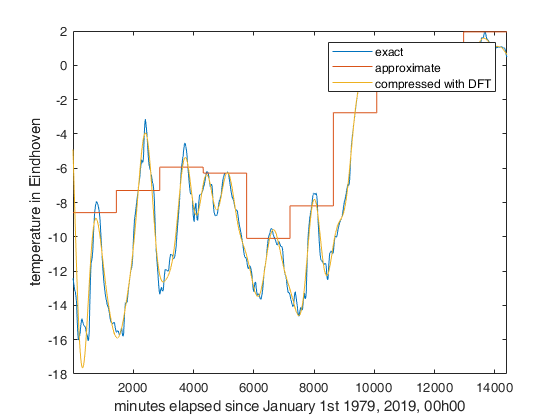

figure(4)
plot([1:10*24*60],weatherEindhoven(1:10*24*60)), hold on, 
plot([1:10*24*60],approxweatherEindhoven(1:10*24*60))
plot([1:10*24*60],compressedWeather(1:10*24*60)), 
axis([1 10*24*60 -18 2])
legend({'exact','approximate','compressed with DFT'})
xlabel('minutes elapsed since January 1st 1979, 2019, 00h00'), ylabel('temperature in Eindhoven')

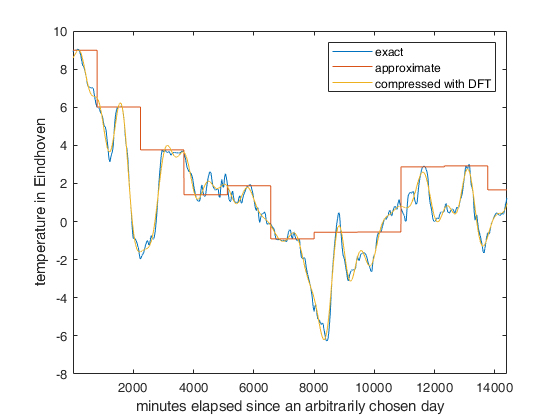



figure(5)
plot([1:10*24*60],weatherEindhoven(1000000:1000000-1+10*24*60)), hold on, 
plot([1:10*24*60],approxweatherEindhoven(1000000:1000000-1+10*24*60))
plot([1:10*24*60],compressedWeather(1000000:1000000-1+10*24*60)), 
axis([1 10*24*60 -8 10])
legend({'exact','approximate','compressed with DFT'})
xlabel('minutes elapsed since an arbitrarily chosen day'), ylabel('temperature in Eindhoven')

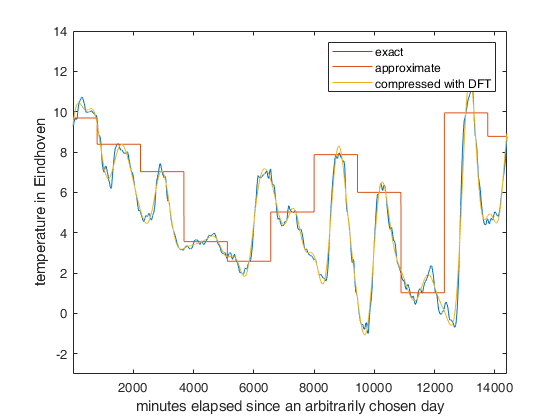


figure(6)
plot([1:10*24*60],weatherEindhoven(100000:100000-1+10*24*60)), hold on, 
plot([1:10*24*60],approxweatherEindhoven(100000:100000-1+10*24*60))
plot([1:10*24*60],compressedWeather(100000:100000-1+10*24*60)), 
legend({'exact','approximate','compressed with DFT'})
axis([1 10*24*60 -3 14])
xlabel('minutes elapsed since an arbitrarily chosen day'), ylabel('temperature in Eindhoven')

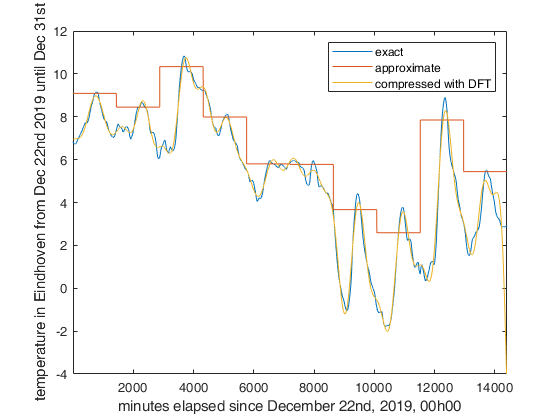



figure(7)
plot([1:10*24*60],weatherEindhoven(end-10*24*60+1:end)), hold on
plot([1:10*24*60],approxweatherEindhoven(end-10*24*60+1:end)), % plot for last 10 days 
plot([1:10*24*60],compressedWeather(end-10*24*60+1:end))
axis([1 10*24*60 -4 12])
legend({'exact','approximate','compressed with DFT'})
xlabel('minutes elapsed since December 22nd, 2019, 00h00'), ylabel('temperature in Eindhoven from Dec 22nd 2019 until Dec 31st')

## Suggestions for follow-up work and variations

- Think on how signals and systems & the DFT can help the world becoming a better place, and in particular help fighting global warming.

- Study the trade-off in selecting the compression ratio $R$.

- Think and share your conclusions about the following questions. What advantages would there be in chopping the signal into several small signals and applying the DFT to each like in the JPEG format?

- Apply compression with DFT to a settting where you think this could be very useful and share your findings.

- Can you think of smarter ways to compress the data using the DFT instead of using a cuttoff frequency? (for instance, thresholding the low energy frequencies or choosing 1000 frequencies with the most energy)